## 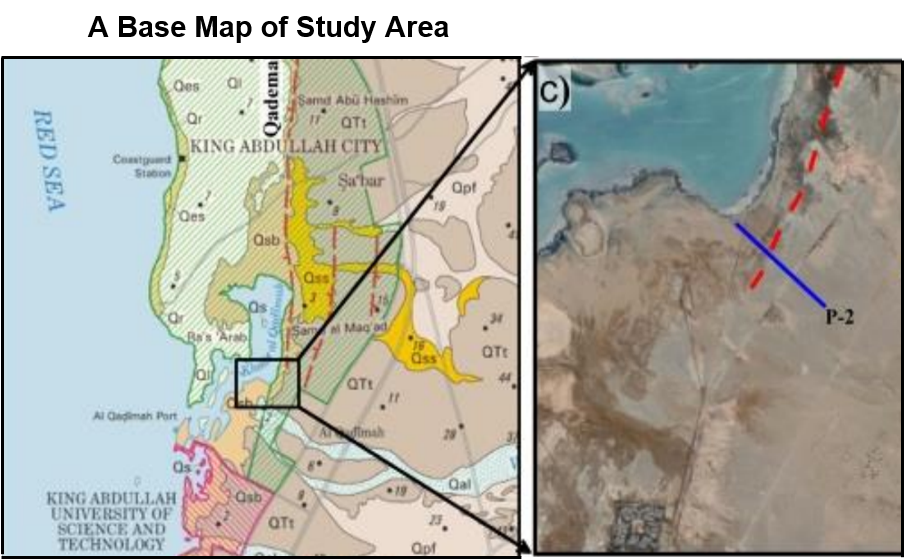

## prapare the data

simple preprocess

load('testdatamat.mat')
% imagesc(seismo_v_d)
% imagesc(seismoPocs)

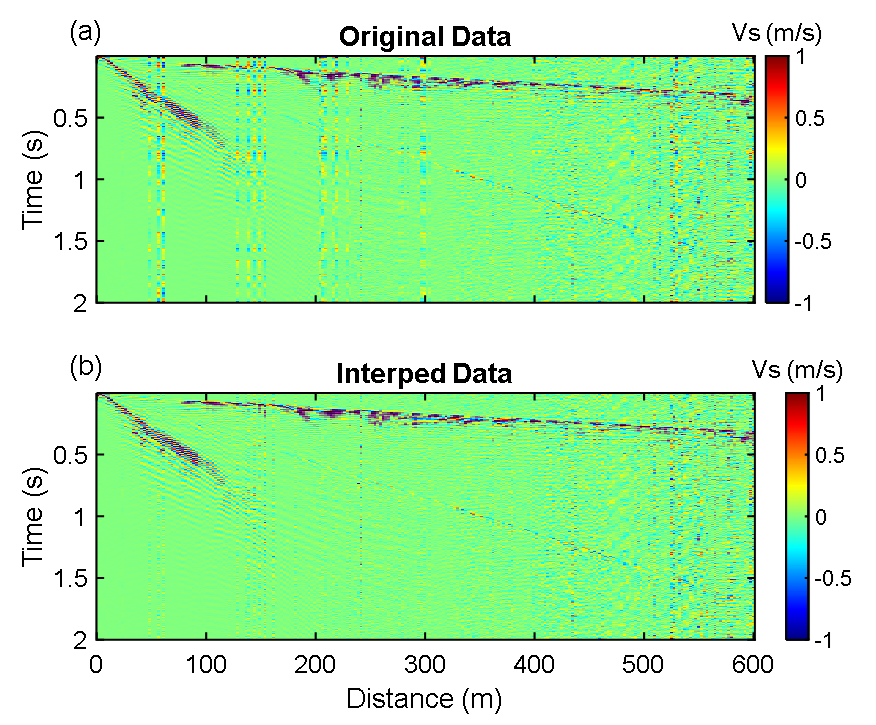

## Extract dispersions

clc;
clear
close all;
load('manualDispfile3of3.mat')
addpath('./core');

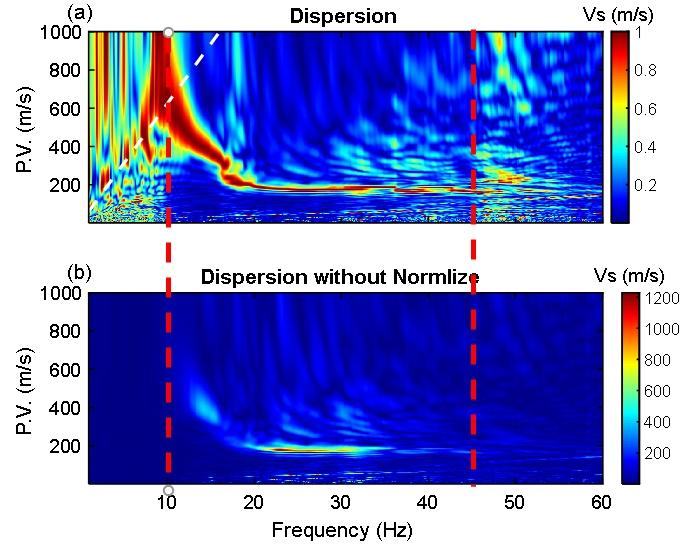


$$\mathrm{Inversion}\;\mathrm{Depth}\approx \frac{\lambda }{2}=\frac{1}{2}\frac{{\mathrm{PV}}_{\max } }{\mathrm{fr}}\approx \frac{65}{10*2}=32\ldotp 5$$


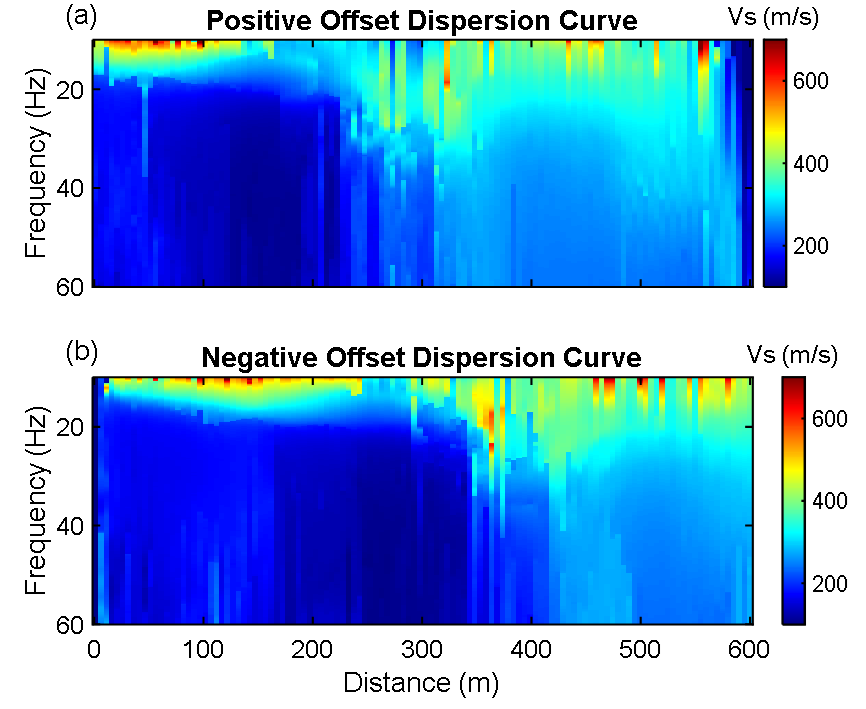

vsmin=100;vsmax=1200;% vsmin=vsmin,vsmax=vsmax*1.6 
vpmin=vsmin*.1732;vpmax=vsmax*1.732;


Maxoffset=39; Minoffset=6;offset=offset-3;

30/2.5=12 offset

Dispersion number:12*2*120= 2880

Maxoffset > Inversion Depth

Maxoffset < The maximum offset that dispersion looks good

## Determine the frequency

Prediction data main frequency = observation data center frequency

fr=30;

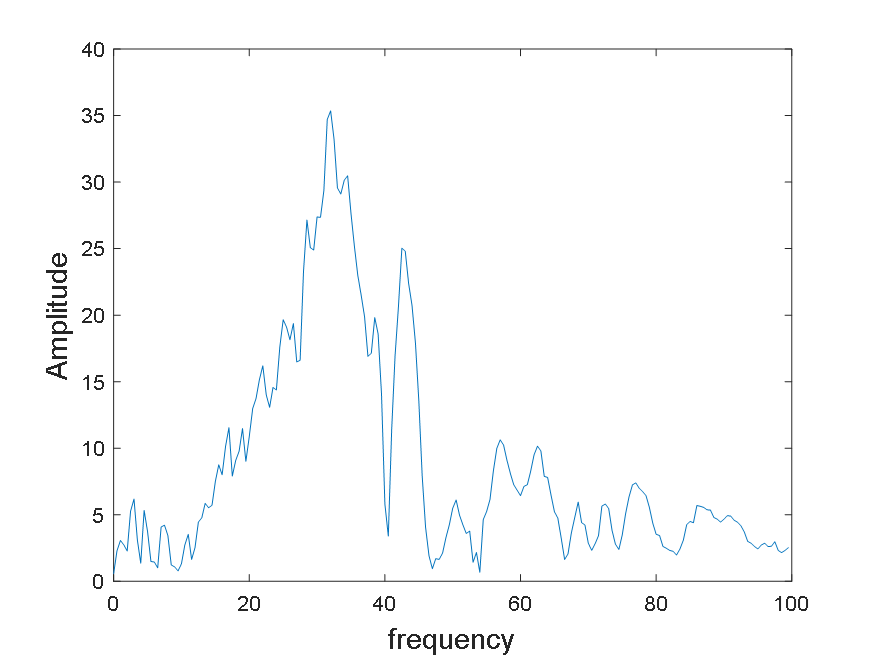

## Determine dx


$$\mathrm{dx}=\frac{{\mathrm{vs}}_{\min } }{\;\mathrm{fr}\times 12}=\frac{100}{30*12}=0\ldotp 2778>0\ldotp 25$$


The geophones are placed on a grid so that dx can only be selected: $\frac{1}{n}$

If dx=0.5


$${\mathrm{vs}}_{\min } =\mathrm{dx}\times \mathrm{fr}\times 12=180$$


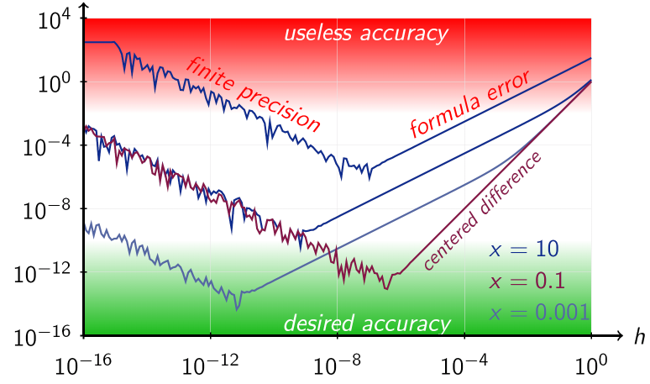

dx=0.25;%dx=(min(vs_d(:))/fr/12);
nz=120;nx=2400;% 30/dx;600/dx
dt=dx/vpmax*0.5;
dtx=dt/dx;

## prapare the data

for i=1:nx
    vs(:,i)=linspace(200,1100,nz);
end
vp=vs*1.732;
pickMethod=1;  %1==FDC 2==argmax
nt=8500;  % time step
[s,nw]=ricker(fr,dt,nt); s =single(s); % source wavelet
nbc=40;   % boundary layer
dt_wf=dt*10; nt_wf=floor((nt-1)*dt/dt_wf)+1;

•Easy equation to calculate memory usage:


$$\left(\mathrm{nz}+\mathrm{nbc}\right)*\left(\mathrm{nx}+\mathrm{nbc}*2\right)*\mathrm{nt}/\mathrm{in}\_\mathrm{wf}*4*4\left(8\right)/1024/1024/1024*\mathrm{ns}\_\mathrm{parallel}\approx 301\ldotp 5518\mathrm{GB}$$


Inversiontime: 4h (AMD EPYC 9684X 96-Core Processor)

The near-surface grid is finer and the computational requirements depend on the velocity range.

% define acquisition geometry
ds=20; sx=single(1:ds:nx); sz=zeros(size(sx),'single')+1;[~,ns]=size(sx);
dg=10;gx=single(1:dg:nx);  gz=zeros(size(gx),'single')+1;  ng=numel(gx);
M=ds/dg;refsx=floor(sx/dg)+1;
dg=dg*dx;
% define wavefield record
pur=-0.05;
offset=floor(1.5*nz*dx);   % multi-offset &the maximum offset
offset=39;
offmin=3;offmax=floor(1.5*nz*dx);
NN=(offset-offmin)/3;   % offset change number
parameter_type=0;
fd_order=22;fsz=0;source_type='w';
isfs=1;

parallel_init(ns/2);

% Set Radon Transform papramter to cal. phase velocity 
vmin=100;
vmax=1000;
np=vmax-vmin+1;
df1=0.1;
df=1/nt/dt;
N=df/df1;
df=df1;
fre1=(df*(0:floor(nt)-1));
fmin=10;
fmax=60;
m=0;FK=0;w=3;  % dot not need to change,w=3 is the min. traces for your multi-offset dispersion. You can increase the number
err=0.01;
a=nt;b=ng;
iteration=190;

## ++++Start SWD iversion ++++

%%--------------------------------------------------------------
k =1;kk=1;
vs_all=zeros(nz,nx,100);
dk_vs_all=zeros(nz,nx,100);
ind=find(fre1==fmin);
freq=(fmin:df:fmax);   
[~,npair]=size(freq);
win=npair+2*ind;
SoftArgNorm = 1e+4;
offsets = zeros(iteration,1);

for i =1:npair
    space_M(:,i) = linspace(1,np,np);
end
[s,nw]=ricker(fr,dt,nt); s =single(s); % source wavelet

while (k<=iteration)  
    tic;
    display(['Elastic_LSM, k=',num2str(k),' iteration=',num2str(iteration)]);

fre=2*pi*linspace(fmin,fmax,(fmax-fmin)/df+1);   

ml = zeros(np,npair,ns);
ml1 = zeros(np,npair,ns);

## Cal. the obsdata dispersion curve two sides(Left and right)

fband = round((fmax-1)/df+1);
fstart = round((fmin-1)/df+1);
cr_0 = smooth2a(crObsManualSR(fstart:fband,:,offset/3),2,1);
cr_0l = smooth2a(crObsManualSL(fstart:fband,:,offset/3),2,1);

cr_pre_r = 1.*ones(npair,ns);
cr_pre_l = 1.*ones(npair,ns);
   g_cl=zeros(nz,nx);
   g_cm=zeros(nz,nx);
   g_illum=zeros(nz,nx);

parfor is=1:ns
   [~,seismo_v,wavefield_gradient]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs,isfs,fsz,fd_order,source_type,parameter_type,dt_wf,nt_wf);
   seismo_v = norm_trace(seismo_v);
   saveForBackwardr = 0;
   saveForBackwardl = 0;
        if is<=ns-floor(m/M)-round(w/M)
            [mlr,dataLen,saveForBackwardr]=RTrAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,FK,M); % Cal. the predicetd data dispersion curve for two sides 
            [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,npair,vmin,cr_0(:,is),saveForBackwardr,pickMethod);
            saveForBackwardr.cr_r = cr_pre_r(:,is)-vmin;
        end

        if is>=round(w/M)+floor(m/M)+1
            [mll,dataLen,saveForBackwardl]=RTlAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,FK,M); % Cal. the predicetd data dispersion curve for two sides 
            [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,npair,vmin,cr_0l(:,is),saveForBackwardl,pickMethod);
            saveForBackwardl.cr_l = cr_pre_l(:,is)-vmin;
        end
        grad_outputr = cr_pre_r(:,is)-cr_0(:,is);
        grad_outputl = cr_pre_l(:,is)-cr_0l(:,is);
%     [seismo_v_d1]=weight_data_muti3(seismo_v,seismo_v,is,dt,df,offset,dg,0,w,M,m,ns,refsx,win,np,vmin,vmax,fmin,fmax, ...
%     cr_0(:,is),cr_0l(:,is),cr_pre_r(:,is),cr_pre_l(:,is),FK,ind); %The key step to calculate the backprohated data
[seismo_v_d1]=ADWDgrad_1(nt,ng,ns,npair,is,w,m,M,SoftArgNorm,grad_outputr,grad_outputl,space_M,saveForBackwardr,saveForBackwardl);
        [cl_img,cm_img,illum_div]=e2drtm_eigen(wavefield_gradient,single(seismo_v_d1),is,nbc,nt,dtx,dx,dt,gx,gz,s,vp,vs,isfs,fsz,fd_order,parameter_type,dt_wf);
        g_cl = g_cl+cl_img;g_cm = g_cm+cm_img;g_illum = g_illum+illum_div;
end

    % Use the penality method to build the objective function
  residual(k)=mean(mean(res_l));%+mean(mean(res_l));
    display(['residual = ',num2str( residual(k) ),' k=',num2str(k)]);
    res0=residual(k); 
    g_cl=g_cl./g_illum;g_cm=g_cm./g_illum;
    dk_vs = -4*vs.*g_cl+2*vs.*g_cm;
    dk_vs=single(smooth2a(double(dk_vs),1,13));  % Smooth the Vs gradient

    if k==1
        f1=0.5;
    end
    v_mean=(sum(vs(:).*vs(:)))^0.5;
    g_mean=(sum(dk_vs(:).*dk_vs(:)))^0.5;
    alpha=v_mean/g_mean*pur;  
    display(['v_mean=',num2str(v_mean),' g_mean=',num2str(g_mean),' alpha=',num2str(alpha)]);
    vs1=vs+alpha*f1*dk_vs;
    vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax; 
    vp=vs1*1.732;
    %vs1(vp./vs1<1.3)=vp(vp./vs1<1.3)/1.3;


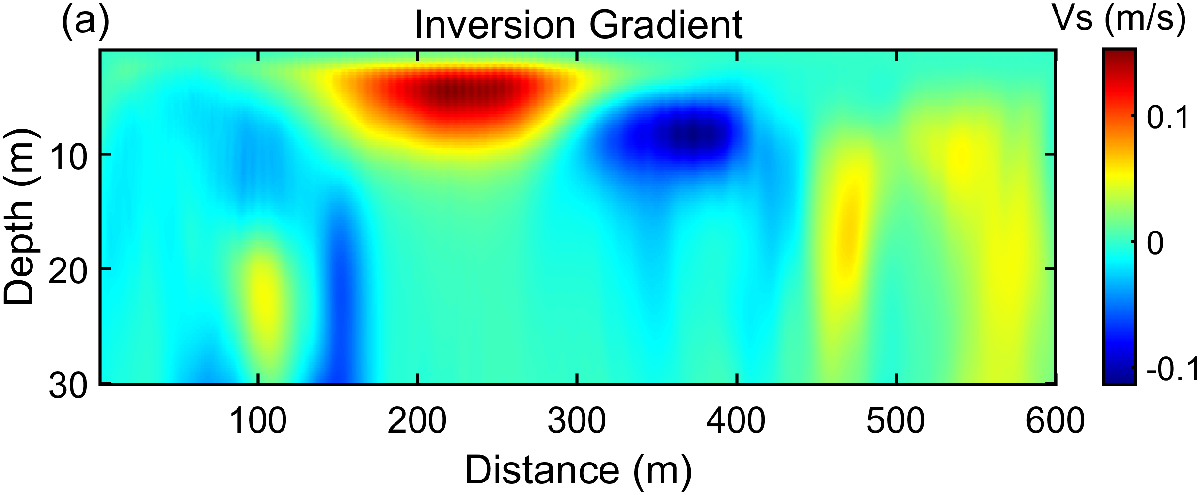

## Result

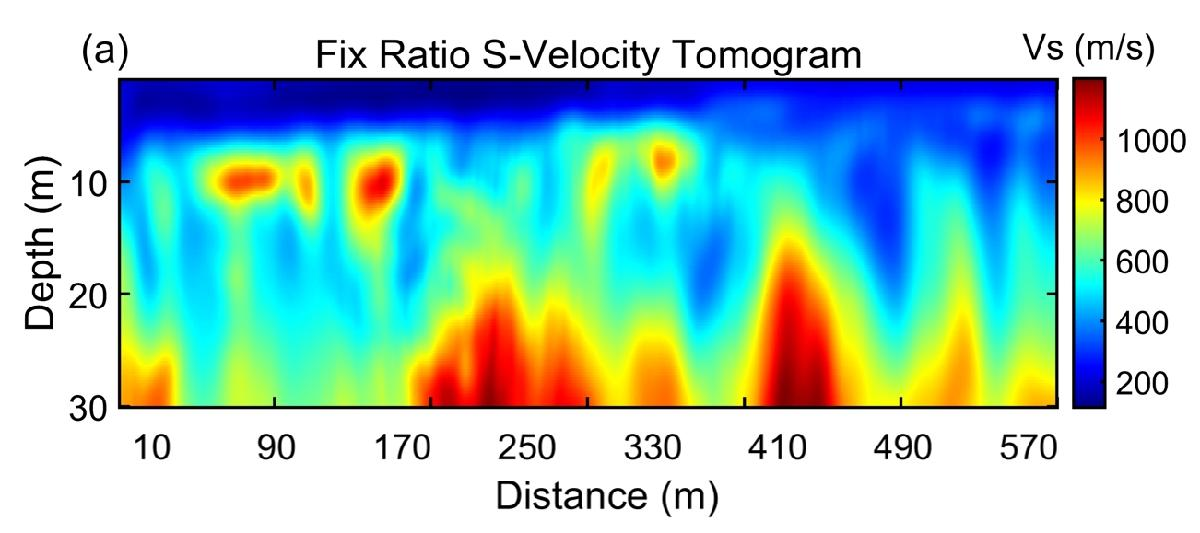

## Evaluation

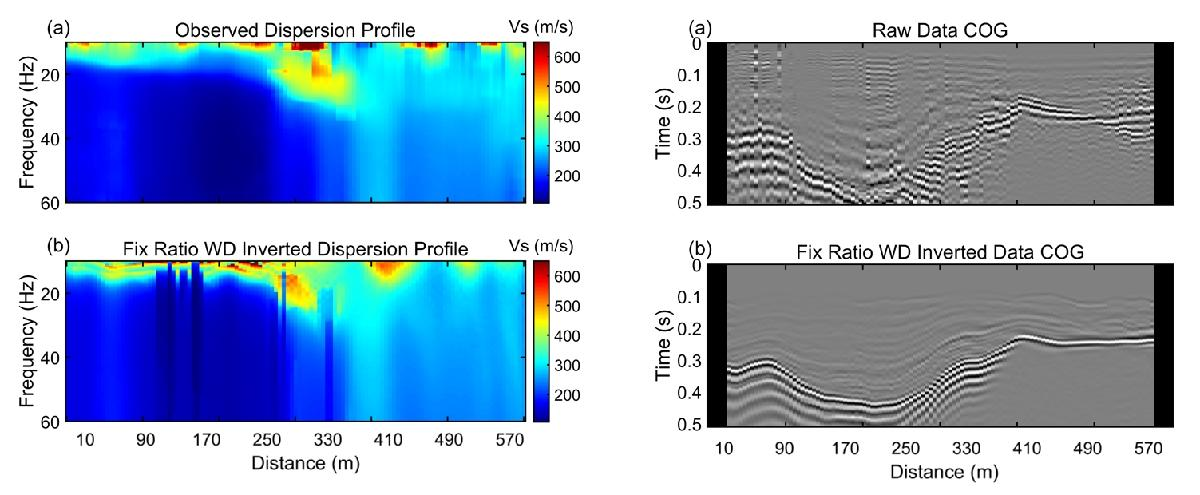

## Misfit